# Práctica 6b. Métodos predictor-corrector

## Método PC on AB-2 y AM-2

El método predictivo AB-2


$$\mathbf U_{i+1}^{[0]} = \mathbf U_i + \frac h 2 (  3 \mathbf f_{i}  - \mathbf f_{i-1}  )$$


Y el método corrector AM-2, para $k=0,\cdots, m-1$


$$\mathbf U_{i+1}^{[k+1]} = \mathbf U_i + \frac h {12} (5 \mathbf f_{i+1}^{[k]} + 8 \mathbf f_{i} - \mathbf f_{i-1})$$


Inicializamos con el método de Heun (Euler mejorado). La implementación se encuentra en el Apéndice.

## Prueba de uso

%% Ecuación
f  = @(t,u) u;

u0 = 1;
t0 = 0;
T  = 5;
interv = [t0,T];

m = 2;
N = 10;

[t,U] = PC_AB2_AM2(f,u0,interv,m,N);

## Comparación

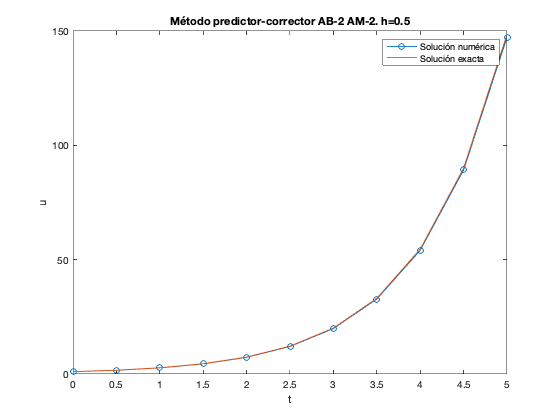

% Grafica
plot(t,U,'o-','DisplayName','Solución numérica')


hold on
plot(t,exp(t),'DisplayName','Solución exacta')
hold off

xlabel('t')
ylabel('u')
h = (T-t0)/N;
title(['Método predictor-corrector AB-2 AM-2. h=' num2str(h)])
legend()

## Error

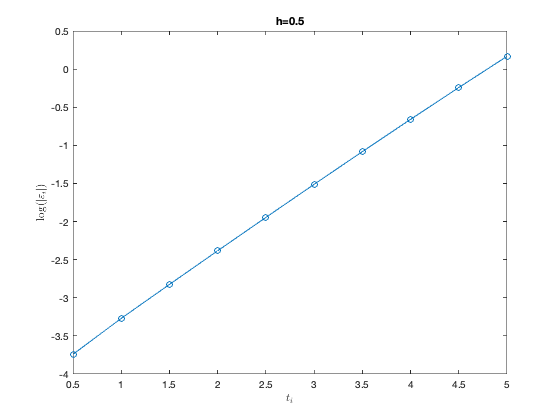

% Valor
figure()

err = abs(U-exp(t));

plot(t,log(err),'o-')
xlabel('$t_i$','Interpreter','latex')
ylabel('$\log(|\varepsilon_i|)$','Interpreter','latex')
title(['h=' num2str(h)])

## Diagrama de eficiencia

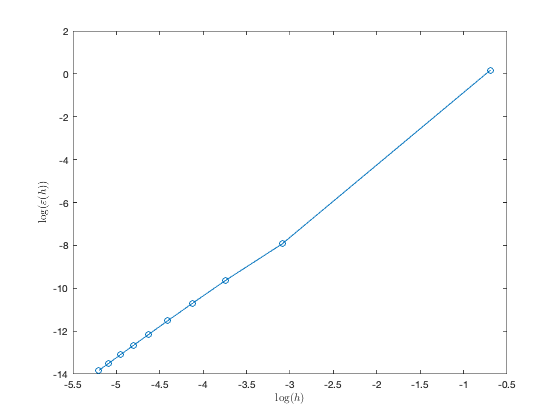

clear err
figure()
NN = 10:100:1000;
hh = (T-t0)./NN;
for i=1:length(NN)
    [t,U] = PC_AB2_AM2(f,u0,interv,m,NN(i));
    err(i) = max(abs(U-exp(t)));
end

figure()
plot(log(hh),log(err),'o-')
xlabel('$\log(h)$','Interpreter','latex')
ylabel('$\log(\varepsilon(h))$','Interpreter','latex')

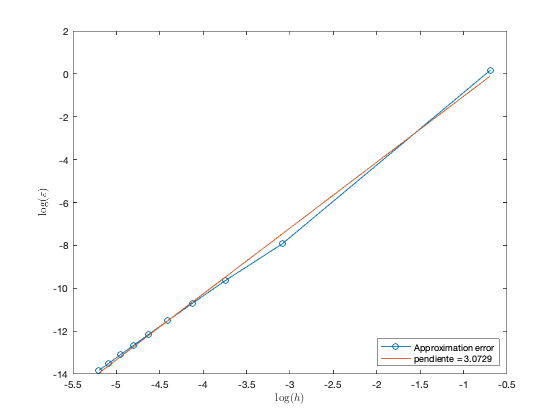

% Pendiente 
P = polyfit(log(hh),log(err),1);
log_err_fit =  P(1) * log(hh) + P(2);

figure()
plot(log(hh),log(err),'o-','DisplayName','Approximation error')

xlabel('$\log(h)$','Interpreter','latex')
ylabel('$\log(\varepsilon)$','Interpreter','latex')

hold on
plot(log(hh),log_err_fit,'DisplayName',['pendiente = ',num2str(P(1))]);
hold off
legend('Location','southeast')

## Apéndice. Método predicción-corrección

function [t,U] = PC_AB2_AM2(f,u0,interv,m,N)
%% PC AB-2 con AM-2 (caso escalar)

t0 = interv(1);
T  = interv(2);

%% Parametro
h = (T-t0)/N;

%% Inicialización
t(1) = t0;
U(1) = u0;
% En metodos multipaso lineales almacenamos de f
ff(1)= f(t(1),U(1));

% Heun
t(2) = t(1) + h;
F1   = f(t(1),U(1)); %ff(1)
F2   = f(t(2),U(1) + h*F1);
U(2) = U(1) + h/2*(F1 + F2);

ff(2)= f(t(2),U(2));

%% Metodo multipaso
for i=2:N   %Pasos a hacer
    t(i+1) = t(i) + h;
    % Prediccion (AB-2)
    U(i+1) = U(i) + h/2 * (3*ff(i) - ff(i-1)); %U_{i+1}^{[0]}
    
    % Evaluacion
    ff(i+1)= f(t(i+1),U(i+1));
    
    for k=1:m
        % Correccion (AM-2)
        U(i+1) = U(i) + h/12 * (5*ff(i+1) + 8*ff(i) - ff(i-1));
        % Evaluacion
        ff(i+1)= f(t(i+1),U(i+1));
    end
end
end